# 6.4 双线性变换法：梯形积分的来历、频率映射的非线性、例 6.7 的变换、例 6.8 带预畸变的完整设计

在 MATLAB 编辑器中打开，点击“运行”；或逐节运行。变换自写（dsp_bilinear：多项式代换），有工具箱时与 bilinear 对照。

clearvars;
LIVE = strcmp(getenv('DSP_LIVE'), '1');
if LIVE, newpanel = @(varargin) figure('Color','w','Position',[80 80 640 420]); else, newpanel = @(varargin) nexttile(varargin{:}); end
if LIVE, set(groot, 'defaultLegendLocation', 'southoutside'); else, set(groot, 'defaultLegendLocation', 'best'); end
here = fileparts(mfilename('fullpath')); if endsWith(here, 'mlx'), here = fileparts(here); end
if ~exist(fullfile(here, 'dsp_freqz.m'), 'file'), here = fileparts(which('dsp_freqz')); end   % Live Script 里 mfilename 为空时靠路径找
codedir = here; addpath(codedir); outdir = fullfile(codedir, 'results'); if ~exist(outdir, 'dir'), mkdir(outdir); end

## 演示1：来历——用梯形法数值积分 y'(t)（教材 6.3.1）：一阶系统 y'+y=x，x(t)=sin t，T 缩小 5 倍误差缩小约 25 倍

Ts = [0.5 0.1]; L = 12; errStep = zeros(1, 2); yStep = cell(1, 2); tStep = cell(1, 2);
exactY = @(t) 0.5*(sin(t) - cos(t) + exp(-t));                        % y'+y=sin t，y(0)=0 的解析解
for i = 1:2
    T = Ts(i); [bz1, az1] = dsp_bilinear(1, [1 1], T);              % Ha(s)=1/(s+1) → 梯形法差分方程
    t = 0:T:L; y = filter(bz1, az1, sin(t));
    errStep(i) = max(abs(y - exactY(t))); yStep{i} = y; tStep{i} = t;
end

## 演示2：频率映射 ω = 2·arctan(ΩT/2)（教材式 (6.3.7)、图 6.3.2）：整个 jΩ 轴压进 (−π, π)，高频压缩得厉害

T = 1; Om = linspace(0, 12, 600); wmap = 2*atan(Om*T/2);
wLin = Om*T;                                                          % 若是线性映射 ω=ΩT
devAt = @(Omega) 100*(Omega*T - 2*atan(Omega*T/2))/(2*atan(Omega*T/2));   % 相对偏离

## 演示3：例 6.7：Ha(s)=(s+1)/(s²+5s+6)：按题设 T=0.001；教材印出的系数其实对应 T=0.01——两个都算

b = [1 1]; a = [1 5 6];
[bzA, azA] = dsp_bilinear(b, a, 0.001);
[bzB, azB] = dsp_bilinear(b, a, 0.01);
bzBook = [4.90172170e-03 4.87733502e-05 -4.85294835e-03]; azBook = [1 -1.95064137 0.95122665];
errBookA = max(abs([bzA - bzBook, azA - azBook])); errBookB = max(abs([bzB - bzBook, azB - azBook]));
% 无混叠：H(e^{jω}) 与 Ha(j(2/T)tan(ω/2)) 逐点相同（式 (6.3.5)）
w = linspace(0, pi - 1e-3, 512); Tb = 0.01;
Hd = dsp_freqz(bzB, azB, w); Hmap = dsp_freqs(b, a, (2/Tb)*tan(w/2)); errMap = max(abs(Hd - Hmap));
errSPT = NaN; if exist('bilinear', 'file') == 2, [bS, aS] = bilinear(b, a, 1/Tb); errSPT = max(abs([bS - bzB, aS - azB])); end

## 演示4：例 6.8：切比雪夫 N=4，预畸变 Ωc=(2/T)tan(ωp/2)=0.6498 → 双线性 → H(z)（式 (6.3.12)）；不预畸变作对比

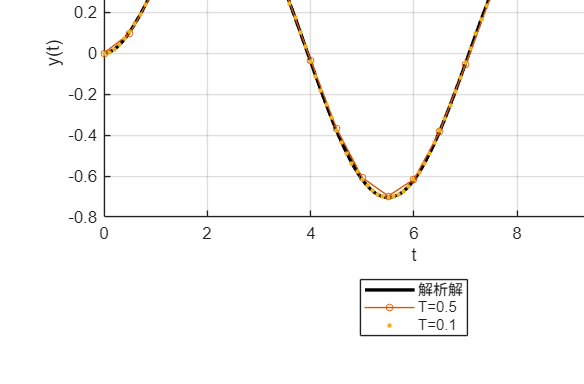

wp = 0.2*pi; ws = 0.3*pi; ap = 1; as = 15; T = 1;
eps = sqrt(10^(ap/10) - 1);
WcPre = (2/T)*tan(wp/2); WsPre = (2/T)*tan(ws/2);
N = ceil(acosh(sqrt(10^(as/10) - 1)/eps)/acosh(WsPre/WcPre));         % 3.014 → 4
[bA, aA] = dsp_cheby1_analog(N, eps, WcPre); [bz8, az8] = dsp_bilinear(bA, aA, T);
azBook8 = conv([1 -1.4996 0.8482], [1 -1.5548 0.6493]); bzBook8 = 0.001836*[1 4 6 4 1];
errBook8 = max(abs([bz8 - bzBook8, az8 - azBook8]));
[bAn, aAn] = dsp_cheby1_analog(N, eps, wp); [bzn, azn] = dsp_bilinear(bAn, aAn, T);   % 不预畸变：直接拿 Ωc=ωp
wd = linspace(0, pi, 1024);
H8 = dsp_freqz(bz8, az8, wd); Hn = dsp_freqz(bzn, azn, wd);
att8 = -20*log10(abs(dsp_freqz(bz8, az8, [wp ws]))); attn = -20*log10(abs(dsp_freqz(bzn, azn, [wp ws])));
wEdgeNoPre = 2*atan(wp*T/2);                                           % 不预畸变时通带边界实际落在的位置

if ~LIVE, f1 = figure('Name','04 双线性变换','Color','w','Position',[60 40 1250 900]); end
if ~LIVE, tiledlayout(2,2,'TileSpacing','compact','Padding','compact'); end
newpanel(); tc = linspace(0, L, 600); plot(tc, exactY(tc), 'k-', 'LineWidth', 2); hold on;
plot(tStep{1}, yStep{1}, 'o-', 'MarkerSize', 4); plot(tStep{2}, yStep{2}, '.', 'MarkerSize', 8); xlim([0 L]);
grid on; xlabel('t'); ylabel('y(t)');
title(sprintf('① 梯形积分实现 y''+y=sin t：T=0.5 误差 %.4f，T=0.1 误差 %.5f（比值 %.0f≈25）', errStep, errStep(1)/errStep(2)));
legend('解析解', 'T=0.5', 'T=0.1');

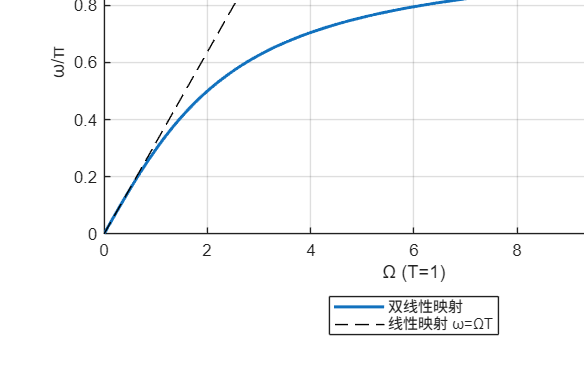

newpanel(); plot(Om, wmap/pi, 'LineWidth', 1.8); hold on; plot(Om, min(wLin, 1.1*pi)/pi, 'k--');
yline(1, 'k:', 'ω=π'); grid on; xlabel('Ω (T=1)'); ylabel('ω/π');
title(sprintf('② ω=2arctan(ΩT/2)：Ω=1 处偏离线性 %.1f%%，Ω=3 处 %.0f%%', devAt(1), devAt(3)));
legend('双线性映射', '线性映射 ω=ΩT');

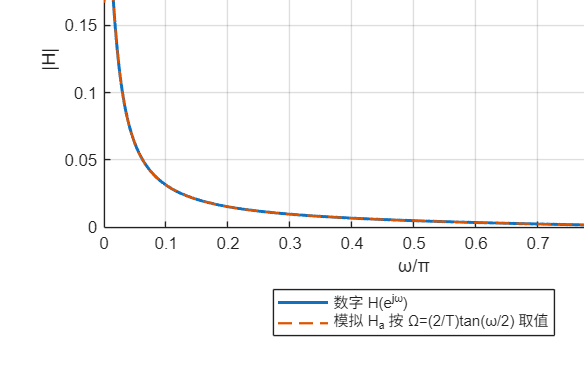

newpanel(); plot(w/pi, abs(Hd), 'LineWidth', 1.8); hold on; plot(w/pi, abs(Hmap), '--', 'LineWidth', 1.4);
grid on; xlabel('ω/π'); ylabel('|H|');
title(sprintf('③ 例 6.7（T=0.01）：H(e^{jω}) 与 H_a(j(2/T)tan(ω/2)) 差 %.0e；与教材系数差 %.0e', errMap, errBookB));
legend('数字 H(e^{jω})', '模拟 H_a 按 Ω=(2/T)tan(ω/2) 取值');

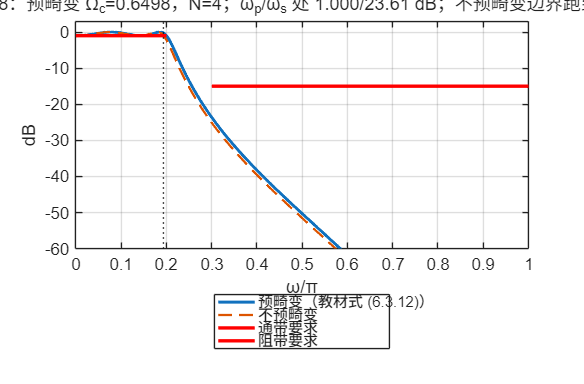

newpanel(); plot(wd/pi, 20*log10(abs(H8)), 'LineWidth', 1.8); hold on; plot(wd/pi, 20*log10(abs(Hn)), '--', 'LineWidth', 1.4);
plot([0 wp/pi], [-ap -ap], 'r-', 'LineWidth', 2); plot([ws/pi 1], [-as -as], 'r-', 'LineWidth', 2); xline(wEdgeNoPre/pi, 'k:');
grid on; ylim([-60 3]); xlabel('ω/π'); ylabel('dB');
title(sprintf('④ 例 6.8：预畸变 Ω_c=%.4f，N=%d；ω_p/ω_s 处 %.3f/%.2f dB；不预畸变边界跑到 %.3fπ', WcPre, N, att8(1), att8(2), wEdgeNoPre/pi));
legend('预畸变（教材式 (6.3.12)）', '不预畸变', '通带要求', '阻带要求');

if ~LIVE, sgtitle('双线性变换：来自梯形积分，稳定性保持、无混叠，代价是频率轴被 tan 压缩——所以先预畸变'); end
if ~LIVE, prepare_export(f1); end
if ~LIVE, exportgraphics(f1, fullfile(outdir, '04-bilinear.png'), 'Resolution', 150); end

## 教师核验

assert(errStep(1)/errStep(2) > 15 && errStep(1)/errStep(2) < 35, '梯形法误差应约按 T² 缩小');
assert(abs(wmap(end) - 2*atan(6)) < 1e-12 && all(wmap < pi), '频率映射不符');
assert(errBookB < 1e-6 && errBookA > 1e-3, '例 6.7：教材系数应对应 T=0.01');
assert(errMap < 1e-9, '式 (6.3.5) 核验失败');
assert(N == 4 && errBook8 < 2e-4, '例 6.8 结果与教材不符');
assert(att8(1) <= ap + 1e-6 && att8(2) >= as, '例 6.8 指标核验不符');
assert(isnan(errSPT) || errSPT < 1e-9, '与 bilinear 不符');
metrics = struct('matlab_version', version, 'run_at', char(datetime('now','Format','yyyy-MM-dd HH:mm:ss')), ...
    'trapezoid_T', Ts, 'trapezoid_err_sin_input', errStep, 'map_dev_percent_at_1_3', [devAt(1) devAt(3)], ...
    'ex67_bz_T0001', bzA, 'ex67_az_T0001', azA, 'ex67_bz_T001', bzB, 'ex67_az_T001', azB, 'ex67_err_book_T0001', errBookA, 'ex67_err_book_T001', errBookB, ...
    'err_no_alias', errMap, 'err_vs_bilinear', errSPT, 'ex68_Wc_prewarped', WcPre, 'ex68_N', N, 'ex68_bz', bz8, 'ex68_az', az8, 'ex68_err_vs_book', errBook8, ...
    'ex68_att_wp_ws', att8, 'noprewarp_att_wp_ws', attn, 'noprewarp_edge_over_pi', wEdgeNoPre/pi, 'all_checks_passed', true);
fid = fopen(fullfile(outdir, 'verification-bilinear.json'), 'w', 'n', 'UTF-8'); assert(fid >= 0);
fprintf(fid, '%s\n', jsonencode(metrics, PrettyPrint=true)); fclose(fid);
disp(metrics); fprintf('\n课堂图已保存到：%s\n', outdir);

             matlab_version: '25.2.0.3360999 (R2025b) Update 7'
                     run_at: '2026-09-18 21:31:39'
                trapezoid_T: [0.5000 0.1000]
    trapezoid_err_sin_input: [0.0141 5.5547e-04]
     map_dev_percent_at_1_3: [7.8405 52.6261]
              ex67_bz_T0001: [4.9900e-04 4.9875e-07 -4.9850e-04]
              ex67_az_T0001: [1 -1.9950 0.9950]
               ex67_bz_T001: [0.0049 4.8773e-05 -0.0049]
               ex67_az_T001: [1 -1.9506 0.9512]
        ex67_err_book_T0001: 0.0444
         ex67_err_book_T001: 4.4433e-10
               err_no_alias: 2.0718e-14
            err_vs_bilinear: 3.7297e-17
          ex68_Wc_prewarped: 0.6498
                     ex68_N: 4
                    ex68_bz: [0.0018 0.0073 0.0110 0.0073 0.0018]
                    ex68_az: [1 -3.0543 3.8290 -2.2925 0.5507]
           ex68_err_vs_book: 7.8853e-05
             ex68_att_wp_ws: [1.0000 23.6074]
        noprewarp_att_wp_ws: [2.2004 25.1034]
     noprewarp_edge_over_pi: 0.1938
       


function prepare_export(fig)
axesList = findall(fig, 'Type', 'axes');
for a = 1:numel(axesList), axesList(a).Toolbar.Visible = 'off'; end
drawnow;
end